# Regresión Lineal por Mínimos Cuadrados

Autor: LUIS JAVIER ONTAÑÓN GARCÍA PIMENTEL. 

Institución: COORDINACIÓN ACADÉMICA REGIÓN ALTIPLANO OESTE, UNIVERSIDAD AUTÓNOMA DE SAN LUIS POTOSÍ

## Resumen

Esta actividad tiene como objetivo reforzar el conocimiento en métodos matemáticos computacionales, específicamente la ecuación de la recta a través del método de regresión lineal. En el ejercicio, aprenderás a ajustar una ecuación de la recta para simular puntos de prueba arbitrarios en el plano cartesiano.

## Objetivos de Aprendizaje

El ejercicio busca proporcionar una comprensión práctica y teórica de la regresión lineal y su implementación en Matlab, al mismo tiempo que desarrolla habilidades críticas en el análisis de datos y la programación.

## Antes de empezar 

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Sección 1: Introducción a la regresión lineal 

La regresión lineal por mínimos cuadrados es un método estadístico utilizado para encontrar la relación lineal entre dos variables. A continuación, se describen los conceptos matemáticos clave relacionados con este método:

**1. Recta de Regresión Lineal: **La recta de regresión lineal se utiliza para modelar la relación entre una variable dependiente $y$ y una variable independiente $x$. La ecuación de la recta se expresa como:

$y=a\;x+b$.                                                (1)

**2. Pendiente (**$a$**)**: La pendiente de la recta, $a$, indica la tasa de cambio de la variable dependiente $y$ por unidad de cambio en la variable independiente $x$. A partir de le minimización de la suma de los cuadrados de los residuos entre los puntos originales a estudiar y los puntos calculados por la aproximación surgen las siguientes ecuaciones normales simultaneas para el modelo de la regresión lineal:

$a=\frac{n\left(\Sigma \textrm{xy}\right)-\left(\Sigma x\right)\left(\Sigma y\right)}{n\left(\Sigma \textrm{x²}\right)-\left(\Sigma x\right)²}$,                                        (2)

donde $n$ es el número de puntos en la secuencia o el número de datos; $\Sigma \textrm{xy}$ es la suma de los productos de cada par de puntos; $\Sigma x$ es la suma de los valores de $x$; $\Sigma y$ es la suma de los valores de $y$; y $\Sigma \textrm{x²}$ es la suma de los cuadrados de los valores de $x$.

**3. Intersección (**$b$**):** La intersección, $b$, es el punto donde la recta de regresión cruza el eje $y$. Se calcula mediante la fórmula:

$b=\frac{\left(\Sigma y\right)\left(\Sigma \textrm{x²}\right)-\left(\Sigma x\right)\left(\Sigma \textrm{xy}\right)}{n\left(\Sigma \textrm{x²}\right)-\left(\Sigma x\right)²}$.                                    (3)

Otra forma de calcular el valor de $b$, es a partir de métodos estadísticos. 

$b=\bar{y} -a\bar{x}$,                                                     (4)

en donde $\bar{x}$ y $\bar{y}$ son las medias de cada vector $x$ y $y$, respectivamente. Véase la referencia [A] para mayor información.

**4. Error Cuadrático Medio (ECM): **El ECM es una medida de la precisión de la recta de regresión. Calcula la media de los cuadrados de las diferencias entre los valores observados $y_i$ y los valores predichos $\hat{\;y_i }$. La fórmula es:

$\textrm{ECM}=\frac{\;1}{n}\sum_{i=1}^n {\left(y_i -\hat{\;y_i } \right)}^2$,                                     (5)

Un ECM más bajo indica un mejor ajuste de la recta a los datos.

**5. Mínimos Cuadrados: **El método de mínimos cuadrados minimiza la suma de los cuadrados de las diferencias entre los valores observados y los valores predichos por la recta de regresión. Esta minimización garantiza que la línea ajustada tenga la menor desviación posible de los puntos de datos.

**6. Residuos: **Los residuos son las diferencias entre los valores observados y los valores predichos por la recta de regresión. Se utilizan para evaluar la calidad del ajuste y detectar posibles patrones no lineales en los datos.

## Sección 2: Definición de recta por el modelo lineal

En esta sección se ajusta una ecuación de la recta para simular puntos en el plano cartesiano, y posteriormente, encontrar una función mediante regresión lineal que se asemeje a lo presentado por los datos.

% Inicialización de plataforma
clear all
close all
clc

Vamos a diseñar un vector de prueba a partir de una línea recta. A esta, le incluiremos valores aleatorios usando una distribución uniforme. Cada vez que se ejecute este ejercicio, los datos de las variables xi y yi serán diferentes. Ajusta las cotas alfa y beta de la distribución, para determinar cuanta variación tendrá cada uno de los datos dentro del vector de prueba. Mientras más cerca de cero se encuentran, menos variación de línea original

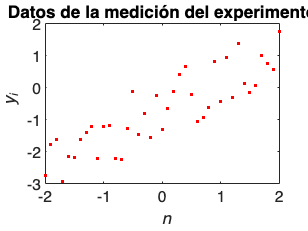

% Datos independientes en el eje horizontal
xi = -2:0.1:2;

% Cotas de la distribución
alfa = -1.9;
beta = 0.4;
% Distribución uniforme
r = (alfa + (beta-alfa).*rand(length(xi),1))'; 

% Datos dependientes en el eje vertical
yi = xi/(1.15)+r;

% Graficación de los puntos de prueba
figure
plot(xi,yi,'r.','MarkerSize',5)
xlabel('\it n')
ylabel( '\it y_i')
title('Datos de la medición del experimento')

drawnow


## Sección 3: Cálculo de los coeficientes de las ecuaciones normales simultáneas

Ahora, calcularemos la pendiente y la intersección y los datos necesario para sus ecuaciones.

n = length(xi);         % Número de datos medidos
Sum_xi = sum(xi);       % Sumatoria de las abscisas medidas
Sum_yi = sum(yi);       % Sumatoria de las ordenadas medidas
Sum_xi2 = sum(xi.^2);
Sum_xiyi = sum(xi.*yi);
media_x = 1/n*Sum_xi;   % Promedio de las abscisas medidas
media_y = 1/n*Sum_yi;   % Promedio de las ordenadas medidas

% Cálculo de la pendiente a dada la ecuación (2)
a = (n*Sum_xiyi-Sum_xi*Sum_yi)/...
    (n*Sum_xi2-Sum_xi*Sum_xi);

% Cálculo de la intersección b dada la ecuación (4)
b = media_y - a*media_x;


El modelo de la regresión lineal de acuerdo a los datos del experimento sería el siguiente:

% Modelo a partir de la regresión lineal
yi_hat = a*xi + b;

## Sección 4: Determinación de los errores y la precisión del modelo calculado.

Para determinar cuál es el grado de precisión de nuestro modelo, es necesario calcular el coeficiente de determinación normalizado, representado por $r^2$. El cuál mide el % de la variabilidad de los datos medidos indicando que tanto la regresión se ajustó a los datos obenidos. Y cuantifica la mejora o reducción del error por describir los datos en términos de una línea recta en vez de un valor promedio en una escala normalizada. Mientras más cerca de 1 se encuentre, mejor y más fiable es la aproximación del módelo

% Cálculo del error entre lo medido y lo calculado
e = yi-yi_hat;

% Suma de los cuadrados de los residuos
Sr = sum(e.^2);

% Suma del error cuadrático de la media
St = sum((yi-media_y).^2);


% Coeficiente de determinación normalizado
fprintf("El coef de determinación es el siguiente:")

El coef de determinación es el siguiente:

r2 = (St-Sr)/St

r2 = 0.7335

fprintf("Nos indica en porcentaje, que tan cerca es la recta a los datos entregados")

Nos indica en porcentaje, que tan cerca es la recta a los datos entregados

fprintf('')


Por último, grafiquemos de nuevo los datos y comparemos con el modelo lineal. 

% Presentación de resultados en formato de tabla
fprintf("A contiuación se muestran los datos y resultados en un formato tabla:")

A contiuación se muestran los datos y resultados en un formato tabla:

Resultados = table(xi',yi',(xi.*xi)',(xi.*yi)',yi_hat',...
                   'VariableNames',{'xi', 'yi','xi2','xiyi','yRL'})

Resultados = 41x5 table
     xi        yi       xi2       xiyi        yRL  
    ____    ________    ____    ________    _______

      -2     -2.7615       4      5.5231    -2.3967
    -1.9     -1.7915    3.61      3.4038     -2.313
    -1.8     -1.6363    3.24      2.9453    -2.2293
    -1.7     -2.9485    2.89      5.0124    -2.1457
    -1.6     -2.1648    2.56      3.4638     -2.062
    -1.5     -2.1795    2.25      3.2692    -1.9783
    -1.4     -1.6309    1.96      2.2832    -1.8946
    -1.3     -1.3989    1.69      1.8186    -1.8109
    -1.2     -1.2077    1.44      1.4492    -1.7272
    -1.1     -2.2217    1.21      2.4438    -1.6436
      -1     -1.2062       1      1.2062    -1.5599
    -0.9     -1.1759    0.81      1.0583    -1.4762
    -0.8     -2.2216    0.64      1.7773    -1.3925
    -0.7      -2.235    0

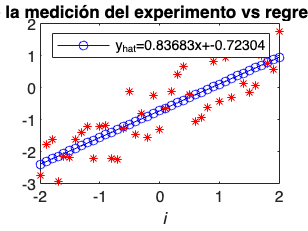


% Graficación de lo calculado por la regresión contra lo medido en un inicio
figure
plot(xi,yi_hat,'bo-','MarkerSize',5)
hold on
plot(xi,yi,'r*','MarkerSize',5)
xlabel('\it i')
title('Datos de la medición del experimento vs regresión lineal')
legend(['y_{hat}=',num2str(a),'x+',num2str(b)])

Por lo tanto la ecuación de la recta aproximada por la regresión sería la siguiente:

% El siguiente es código para mostrar en pantalla la ecuación
sympref('FloatingPointOutput',true);
syms x;
Salida_a = vpa(a,5);
Salida_b = vpa(b,5);
fprintf("La ecuación de la recta aproximada por regresión lineal es:")

La ecuación de la recta aproximada por regresión lineal es:

displayFormula("y_hat = Salida_a*x+Salida_b")

$$\hat{y}=0.8368\,x-0.7230$$

## Ejercicio de práctica

Con lo visto anteriormente, remueve los comentarios % del siguiente cuadro de código, y cálcula los coeficientes de $a$, $b$ y el coeficiente de determinación $r^2$ para la función de regresión lineal de los siguientes datos experimentales:

% Señal de prueba
 % xi = 1:0.25:2;
 % yi = [5.1, 5.79, 6.53, 7.45, 8.46];

## Recursos Adicionales

En esta sección comparta enlaces o referencias adicionales para los educadores y estudiantes que usen este material.

## Referencias 

Para mayor información, consulta las siguientes referencias:

[A] Chapra, S. C., Canale, R. P., Ruiz, R. S. G., Mercado, V. H. I., Díaz, E. M., & Benites, G. E. (2011). *Métodos numéricos para ingenieros* (Vol. 5, pp. 451-482). McGraw-Hill.

[B] Burden, R. L. (2016). *Análisis numérico *(pp. 378-384). CENGAGE Learning, 10a. Edición. 

[C] Cheney, W., Kincaid, D. *Métodos numéricos y computacionales *(pp. 495-517). CENGAGE Learning, 6ta. Edición. 